% Full clean start
clc; clearvars;

% Define the base folder
base_folder = 'extract/';

% Get all contents of the base folder
all_items = dir(base_folder);

% Check that dir() worked
if ~isstruct(all_items)
    error('dir() did not return a struct. Check the "base_folder" path.');
end

% Filter only folders (ignore "." and "..")
subfolders = all_items([all_items.isdir]);
subfolders = subfolders(~ismember({subfolders.name}, {'.', '..'}));

% Display for confirmation
disp('Subfolders found:');

Subfolders found:


disp({subfolders.name});

    {'001'}    {'001_forg'}    {'002'}    {'002_forg'}    {'003'}    {'003_forg'}    {'004'}    {'004_forg'}    {'005'}    {'005_forg'}    {'006'}    {'006_forg'}    {'007'}    {'007_forg'}    {'008'}    {'008_forg'}    {'009'}    {'009_forg'}    {'010'}    {'010_forg'}    {'011'}    {'011_forg'}    {'012'}    {'012_forg'}    {'013'}    {'013_forg'}    {'014'}    {'014_forg'}    {'015'}    {'015_forg'}    {'016'}    {'016_forg'}    {'017'}    {'017_forg'}    {'018'}    {'018_forg'}    {'019'}    {'019_forg'}    {'020'}    {'020_forg'}    {'021'}    {'021_forg'}    {'022'}    {'022_forg'}    {'023'}    {'023_forg'}    {'024'}    {'024_forg'}    {'025'}    {'025_forg'}    {'026'}    {'026_forg'}    {'027'}    {'027_forg'}    {'028'}    {'028_forg'}    {'029'}    {'029_forg'}    {'030'}    {'030_forg'}    {'031'}    {'031_forg'}    {'032'}    {'032_forg'}    {'033'}    {'033_forg'}    {'034'}    {'034_forg'}    {'035'}    {'035_forg'}    {'036'}    {'036_forg'}    {'037'}    {'037_forg'} 

%% Collect Genuine and Forged Image Paths

% Initialize path lists
genuine_paths = {};
forged_paths = {};

% Loop through each subfolder
for i = 1:length(subfolders)
    folder_name = subfolders(i).name;
    folder_path = fullfile(base_folder, folder_name);

    image_files = dir(fullfile(folder_path, '*.jpg'));

    for j = 1:length(image_files)
        full_path = fullfile(folder_path, image_files(j).name);

        if contains(lower(folder_name), 'forg')  % case-insensitive match
            forged_paths{end+1} = full_path;
        else
            genuine_paths{end+1} = full_path;
        end
    end
end

% Show image counts
fprintf('Total genuine images found: %d\n', numel(genuine_paths));

Total genuine images found: 6233


fprintf('Total forged images found : %d\n', numel(forged_paths));

Total forged images found : 6233


TASK 1 - Refining the dataset with atleast 100 images per class

mkdir('refined/genuine');

mkdir('refined/forged');


rng(1); %for reproducibility

genuine_indices = randperm(length(genuine_paths), 150);
forged_indices = randperm(length(forged_paths), 150);

for i = 1:150
    src = genuine_paths{genuine_indices(i)};
    [~, name, ext] = fileparts(src);
    dest = ['refined/genuine/' name ext];
    copyfile(src, dest);
end

for i = 1:150
    src = forged_paths{forged_indices(i)};
    [~, name, ext] = fileparts(src);
    dest = ['refined/forged/' name ext];
    copyfile(src, dest);
end

fprintf('copied 150 genuine and forged images to refined folder.\n');

copied 150 genuine and forged images to refined folder.


TASK 2 - Pre-processing and Feature Extraction Techniques

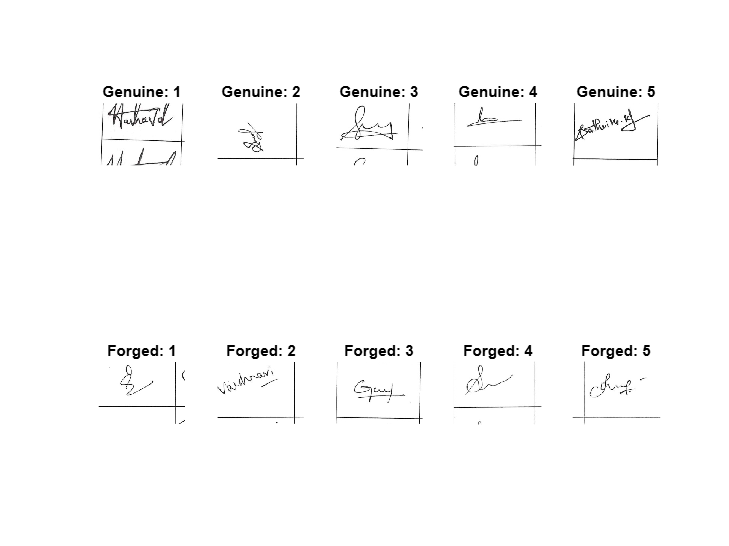

%displaying sample images from both classes
genuine_folder = 'refined/genuine/';
forged_folder = 'refined/forged/';

genuine_files = dir([genuine_folder '*.jpg']);
forged_files = dir([forged_folder '*.jpg']);

num_sample = 5;

figure;
for i = 1:num_sample
    subplot(2, num_sample, i);
    img = imread([genuine_folder genuine_files(i).name]);
    imshow(img);
    title(['Genuine: ', num2str(i)]);

    subplot(2, num_sample, i + num_sample);
    img = imread([forged_folder forged_files(i).name]);
    imshow(img);
    title(['Forged: ', num2str(i)]);
end

The images are already grayscale, so there is no need of converting them into grayscale.

Implementing Canny Edge Detection as part of pre-processing.

The steps for canny edge detection will include the following:

- Smoothing the image to reduce noise by applying gaussian blur filter.

- Using sobel filter for calculating the gradient in x and y directions.

- Thinning the edges by keeping only the maximum in the gradient direction.

- Linking the edges by using low and high thresholds, also known as Edge tracking by Hysteresis.

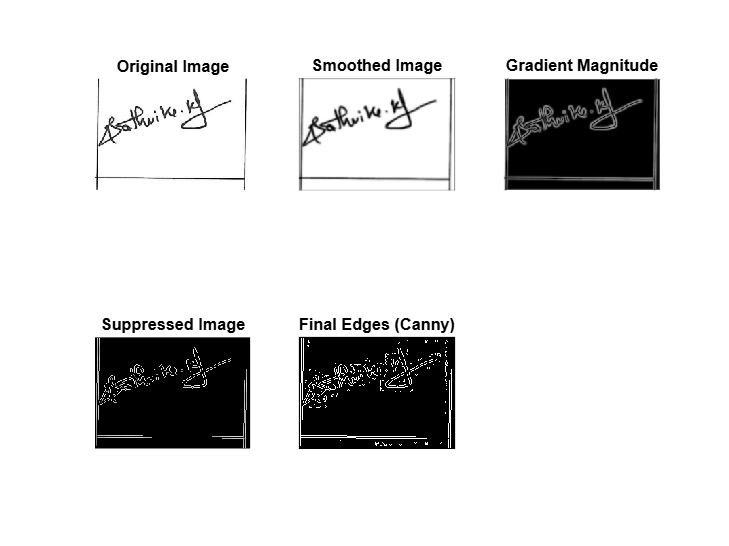

%Gaussian filter
function smooth_image = gaussian_blur(image, sigma)
    size = 2 * ceil(3 * sigma) + 1;
    [x, y] = meshgrid(-floor(size/2):floor(size/2), -floor(size/2):floor(size/2));
    gaussian_kernel = exp(-(x.^2 + y.^2) / (2*sigma^2));
    gaussian_kernel = gaussian_kernel / sum(gaussian_kernel(:));

    smooth_image = conv2(double(image), gaussian_kernel, 'same');
end


%gradient calculation
function [magnitude, direction] = sobel_gradient(image)
    Gx = [-1 0 1; -2 0 2; -1 0 1]; %horizontal gradient filter
    Gy = [-1 -2 -1; 0 0 0; 1 2 1]; %vertical filter

    Ix = conv2(double(image), Gx, 'same');
    Iy = conv2(double(image), Gy, 'same');

    magnitude = sqrt(Ix.^2 + Iy.^2);
    direction = atan2(Iy, Ix);
end

%thinning (non-maximum suppression)
function suppressed_image = non_maximum_suppression(magnitude, direction)
    [rows, cols] = size(magnitude);
    suppressed_image = zeros(rows, cols);

    direction = mod(direction + pi, pi);

    for i = 2:rows-1
        for j = 2:cols-1
            angle = direction(i, j);
            if (angle >= 0 && angle < pi/4) || (angle >= 3*pi/4 && angle < pi)
                neighbor1 = magnitude(i, j+1);
                neighbor2 = magnitude(i, j-1);
            elseif (angle >= pi/4 && angle < 3*pi/4)
                neighbor1 = magnitude(i+1, j);
                neighbor2 = magnitude(i-1, j);
            end
            
            % Compare magnitude with neighbors
            if magnitude(i, j) >= neighbor1 && magnitude(i, j) >= neighbor2
                suppressed_image(i, j) = magnitude(i, j);
            else
                suppressed_image(i, j) = 0;
            end
        end
    end
end

% Edge Tracking by Hysteresis
function final_edges = hysteresis_thresholding(image, low_threshold, high_threshold)
    final_edges = zeros(size(image));
    
    % Apply high threshold first
    final_edges(image > high_threshold) = 1;
    
    % Apply low threshold to weak edges connected to strong edges
    for i = 2:size(image,1)-1
        for j = 2:size(image,2)-1
            if image(i, j) > low_threshold && final_edges(i, j) == 0
                if any(final_edges(i-1:i+1, j-1:j+1) == 1)
                    final_edges(i, j) = 1;
                end
            end
        end
    end
end

% Canny Edge Detection without built-in functions
function edges = canny_edge_detection(image, sigma, low_threshold, high_threshold)
    % Step 1: Apply Gaussian Blurring
    smoothed_image = gaussian_blur(image, sigma);
    
    % Step 2: Compute gradients (Sobel)
    [gradient_magnitude, gradient_direction] = sobel_gradient(smoothed_image);
    
    % Step 3: Apply Non-Maximum Suppression
    suppressed_image = non_maximum_suppression(gradient_magnitude, gradient_direction);
    
    % Step 4: Apply Edge Tracking by Hysteresis
    edges = hysteresis_thresholding(suppressed_image, low_threshold, high_threshold);
    
    % Visualization after each step
    figure;
    subplot(2, 3, 1), imshow(image), title('Original Image');
    subplot(2, 3, 2), imshow(smoothed_image, []), title('Smoothed Image');
    subplot(2, 3, 3), imshow(gradient_magnitude, []), title('Gradient Magnitude');
    subplot(2, 3, 4), imshow(suppressed_image, []), title('Suppressed Image');
    subplot(2, 3, 5), imshow(edges, []), title('Final Edges (Canny)');
end

% Example: Test on a sample image
img = imread([genuine_folder genuine_files(5).name]); % Load a genuine image
img = rgb2gray(img); % Convert to grayscale

% Apply Canny edge detection with visualization
sigma = 1.0; % Standard deviation for Gaussian blur
low_threshold = 0.1; % Low threshold for hysteresis
high_threshold = 0.3; % High threshold for hysteresis
canny_edge_detection(img, sigma, low_threshold, high_threshold);